clear;

tic;

% パラメータの定義
tspan = [0 1.2]; % シミュレーション時間

% CSVデータを事前に読み込む
T = readtable('output44.csv');
start_time = 21; % 開始時間

% 初期値を求める%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
time_data = T{:, 1};
value_data = T{:, 2:4};

% 微分値を計算
diff_value = zeros(size(value_data));
for j = 1:size(value_data, 2)
    for i = 2:length(time_data)-1
        diff_value(i, j) = (value_data(i+1, j) - value_data(i-1, j)) / (time_data(i+1) - time_data(i-1));
    end
    diff_value(1,j) = (value_data(2, j) - value_data(1, j)) / (time_data(2) - time_data(1));
    diff_value(end,j) = (value_data(end, j) - value_data(end-1, j)) / (time_data(end) - time_data(end-1));
end

% 移動平均フィルタ
window_size = 5; % 移動平均の窓幅
filtered_diff_value = zeros(size(diff_value));
for j = 1:size(diff_value, 2)
    filtered_diff_value(:,j) = movmean(diff_value(:,j), window_size);
end

% 時刻がスタートの時のフィルタ後の微分値を求める (前述のコードと同様)
target_time = start_time;
[~, target_index] = min(abs(time_data - target_time));
filtered_diff_value_at_target_time = filtered_diff_value(target_index, :);

disp(['時刻 ', num2str(target_time), ' の時のフィルタ後の微分値 (移動平均): ', num2str(filtered_diff_value_at_target_time)]);

時刻 21 の時のフィルタ後の微分値 (移動平均): -0.96889      1.2973    -0.40866



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



% テーブルの最初の列を取得 (時間データ)
time_data = T{:, 1};

% 論理インデックスを作成
rows_to_keep = time_data >= start_time;

% 条件を満たす行のみを保持
T = T(rows_to_keep, :);
start_att = table2array(T(1, [2 3 4]));
motor_val_csv = table2array(T(:, [5 6 7 8])); % CSVのモーター入力データ
time_csv = time_data(rows_to_keep)-start_time;
real_att = table2array(T(1:tspan(2)*100, [2 3 4]));
real_time = table2array(T(1:tspan(2)*100, 1))-start_time;


運動方程式と回転行列、角速度ベクトルをロード

load("dX.mat", "fdX");
load("R_BtoI.mat", "fR_BtoI");
load("Omega.mat", "fOmega");
load("P_BtoI.mat", "fP_BtoI");
load("P_ItoB.mat", "fP_ItoB");

初期値を設定

X0 = [0; 0; 0];    % 位置
dX0 = [0; 0; 0];   % 速度

eta0 = start_att';   % 角度
deta0 = filtered_diff_value_at_target_time';   % 角速度

Current0 = [X0; eta0; dX0; deta0];

シミュレーションの環境設定

etad=[0;0;pi*0/180];  %目標角

kp = [5; 16; 50]; % 角度制御の比例ゲイン
kd = [6; 6; 5]; % 角度制御の微分ゲイン

setting_val = [etad; kp; kd];

tspan = 0:0.01:tspan(2);      % シミュレーション時間

定数に値を入れる 

J_xx = 0.01; J_yy = 0.01; J_zz = 0.01; 
m = 0.7; g = 9.81; mu_1 = 10; mu_2 = 10; 
const = [J_xx; J_yy; J_zz; m; g; mu_1; mu_2;];

% % 外力 (例: すべて0)
% F_b = [0; 0; 0];
% Tau_b = [0; 0; 0];
% Q_b = [F_b; Tau_b];

ode45でシミュレーション

options = odeset('RelTol',1e-6,'AbsTol',1e-6);
[ta, Current] = ode45(@(t, Current) system_dynamics(t, Current, const, setting_val, fdX, fR_BtoI, fOmega, fP_BtoI, fP_ItoB, time_csv, motor_val_csv), tspan, Current0,options);

シミュレーション結果の取り出し

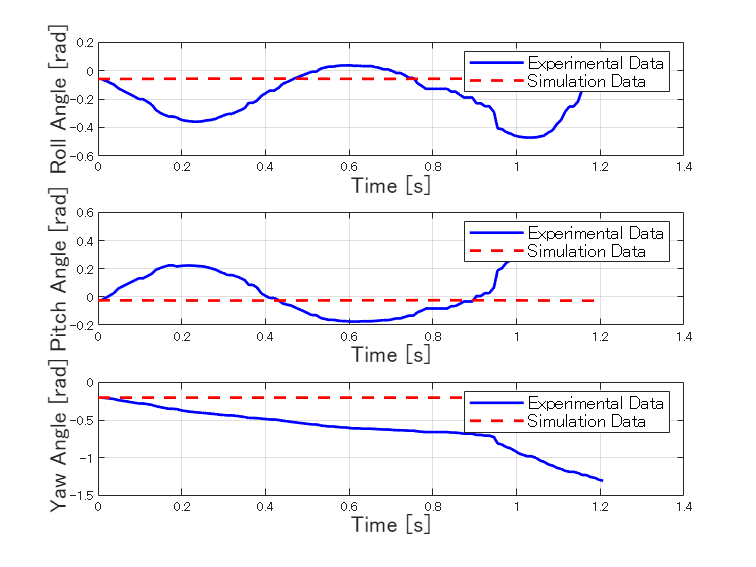

figure(1); clf; % figure(1)を作成またはクリア

% ロール角 (φ)
subplot(3, 1, 1); % 3行1列の1番目のsubplot
plot(real_time, real_att(:,1), 'b-', 'LineWidth', 1.5); % 実験値 (青実線)
hold on;
plot(ta, Current(:,4), 'r--', 'LineWidth', 1.5); % シミュレーション値 (赤破線)
hold off;
% title('(a) I_xx=I_yy=I_zz=0.001','FontSize',14);
xlabel('Time [s]','FontSize',13);
ylabel('Roll Angle [rad]','FontSize',13);
legend('Experimental Data', 'Simulation Data','FontSize',10); % 凡例も英語表記に

grid on;

% ピッチ角 (θ)
subplot(3, 1, 2); % 3行1列の2番目のsubplot
plot(real_time, real_att(:,2), 'b-', 'LineWidth', 1.5); % 実験値 (青実線)
hold on;
plot(ta, Current(:,5), 'r--', 'LineWidth', 1.5); % シミュレーション値 (赤破線)
hold off;
% title('ピッチ角 (θ)');
xlabel('Time [s]','FontSize',13);
ylabel('Pitch Angle [rad]','FontSize',13);
legend('Experimental Data', 'Simulation Data','FontSize',10); % 凡例も英語表記に

grid on;

% ヨー角 (ψ)
subplot(3, 1, 3); % 3行1列の3番目のsubplot
plot(real_time, real_att(:,3), 'b-', 'LineWidth', 1.5); % 実験値 (青実線)
hold on;
plot(ta, Current(:,6), 'r--', 'LineWidth', 1.5); % シミュレーション値 (赤破線)
hold off;
% title('ヨー角 (ψ)');
xlabel('Time [s]','FontSize',13);
ylabel(' Yaw Angle [rad]','FontSize',13);
legend('Experimental Data', 'Simulation Data','FontSize',10); % 凡例も英語表記に

grid on;

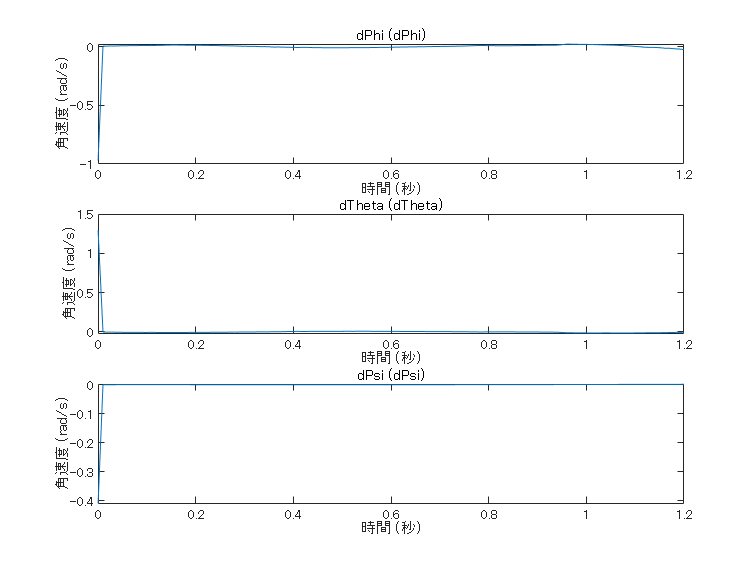




figure(2); clf; hold on;

subplot(3,1,1);
plot(ta, Current(:,10));
title('dPhi (dPhi)');
xlabel('時間 (秒)');
ylabel('角速度 (rad/s)');

subplot(3,1,2);
plot(ta, Current(:,11));
title('dTheta (dTheta)');
xlabel('時間 (秒)');
ylabel('角速度 (rad/s)');

subplot(3,1,3);
plot(ta, Current(:,12));
title('dPsi (dPsi)');
xlabel('時間 (秒)');
ylabel('角速度 (rad/s)');

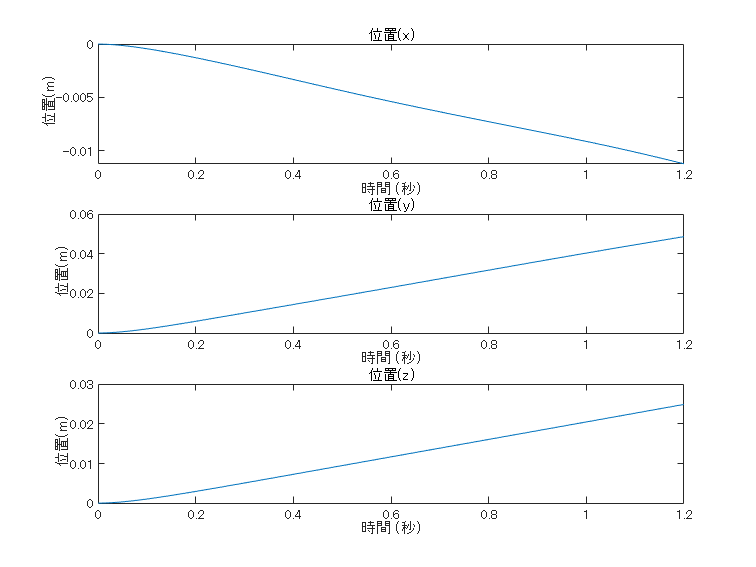


figure(3); clf; hold on;
subplot(3,1,1);
plot(ta, Current(:,1));
title('位置(x)');
xlabel('時間 (秒)');
ylabel(' 位置(m)');
 
subplot(3,1,2);
plot(ta, Current(:,2));
title('位置(y)');
xlabel('時間 (秒)');
ylabel(' 位置(m)');
 
subplot(3,1,3);
plot(ta, Current(:,3));
title('位置(z)');
xlabel('時間 (秒)');
ylabel(' 位置(m)');

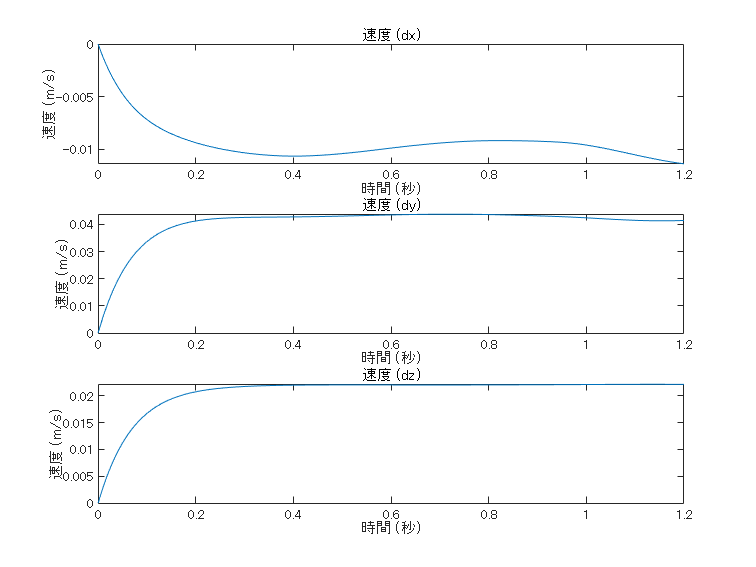


figure(4); clf; hold on;

subplot(3,1,1);
plot(ta, Current(:,7));
title('速度 (dx)');
xlabel('時間 (秒)');
ylabel('速度 (m/s)');

subplot(3,1,2);
plot(ta, Current(:,8));
title('速度 (dy)');
xlabel('時間 (秒)');
ylabel('速度 (m/s)');

subplot(3,1,3);
plot(ta, Current(:,9));
title('速度 (dz)');
xlabel('時間 (秒)');
ylabel('速度 (m/s)');


% system_dynamics
function dCurrent = system_dynamics(t, Current, const, setting_val, fdX, fR_BtoI, fOmega, fP_BtoI, fP_ItoB, time_csv, motor_val_csv)
    % 時間 t に対応するモーター入力値を線形補間 (変更なし)
    if isempty(time_csv)
        motor_val = [0,0,0,0]; % CSVデータがない場合の処理
    else
        for i = 1:length(time_csv)-1
            if t >= time_csv(i) && t <= time_csv(i+1)
                motor_val = motor_val_csv(i,:) + (motor_val_csv(i+1,:) - motor_val_csv(i,:)) * (t - time_csv(i)) / (time_csv(i+1) - time_csv(i));
                break;
            elseif t < time_csv(1)
                motor_val = motor_val_csv(1,:);
                break;
            elseif t > time_csv(end)
                motor_val = motor_val_csv(end,:);
                break;
            end
        end
    end

    X_I = Current(1:3);
    Eta_I = Current(4:6);
    dX_I = Current(7:9);
    dEta_I = Current(10:12);
    X_I = Current;
    % F_b = Q_b(1:3);
    % Tau_b = Q_b(4:6);
    etad_b = setting_val(1:3);
    kp = setting_val(4:6);
    kd = setting_val(7:9);

    % 各種変換行列を作る
    R_BtoI = fR_BtoI(Eta_I);
    Omega = fOmega([Eta_I; dEta_I]);
    P_BtoI = fP_BtoI(Eta_I);
    P_ItoB = fP_ItoB(Eta_I);

    % 慣性座標系の角度と角速度を機体座標系に変換
    Eta_b =  P_ItoB * Eta_I;
    dEta_b = P_ItoB * dEta_I;

    motor_torq_roll =  sum(motor_val *diag([-1 -1 1 1])*0.022191707538092*0.1425);
    motor_torq_pitch =  sum(motor_val *diag([1 -1 1 -1])*0.022191707538092*0.090);
    motor_torq_yaw =  sum(motor_val *diag([-1 1 1 -1])*3.533461241187303e-04);
    motor_torq = [motor_torq_roll;motor_torq_pitch;motor_torq_yaw];

    F_b = [0; 0; 1] * 80 * 0.022191707538092 * 4;
    Tau_b = motor_torq;

    F_I = R_BtoI * F_b;
    Tau_I = P_BtoI * Tau_b;
    Q_I = [F_I; Tau_I];

    vars = {[X_I; Q_I; const]};
    fdx_val = fdX(vars{:});
    dCurrent = fdx_val;
end